%-------------------------------------------------------------------------%
% 1SN - TP Optimisation                                                   %
% INP Toulouse - ENSEEIHT                                                 %
% Novembre 2020                                                           %
%                                                                         %
% Ce fichier contient le programme principal permettant l'estimation      %
% des parametres de la fonction de desintegration radioactive du          %
% carbone 14 par une approche des moindres carres.                        %                                      %
% Modele : A(t)= A0*exp(-lambda*t)                                        %
% Les algorithmes utilises pour la minimisation sont :                    %
% - l'algorithme de Gauss-Newton                                          %
% - l'algorithme de Newton.                                               %
%-------------------------------------------------------------------------%

clear
close all
clc
format shortG
taille_ecran = get(0,'ScreenSize');
L = taille_ecran(3);
H = taille_ecran(4);

% Initialisation

% Donnees
if exist('C14_results.txt','file')
    delete('C14_results.txt');
end
diary C14_results.txt
Ti = [ 500; 1000; 2000; 3000; 4000; 5000; 6300];
Ai = [14.5; 13.5; 12.0; 10.8;  9.9;  8.9;  8.0];
Donnees = [Ti, Ai];

% Estimation a priori des parametres du modele : beta0 = [A0, lambda]
beta0 = [10; 0.0001];   % Newton, Gauus-Newton, fminunc et leastsq converge
% beta0 = [15; 0.001];    % Newton, Gauss-Newton, fminunc et leastsq divergent
% beta0 = [15; 0.0005];   % Newton diverge, Gauss-Newton, fminunc et leastsq convergent
% beta0 = [10; 0.0005];   % Gauss-Newton converge

## Calcul et affichage du modele initial ----------------------------------

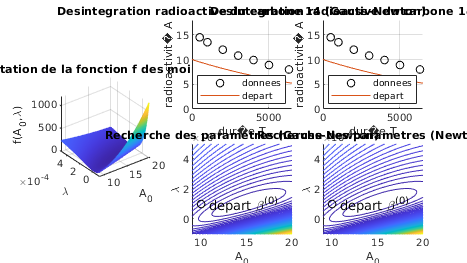

xmin = 9; xmax = 20;
x = linspace(xmin, xmax, 100);

ymin = -0.0001; ymax = 0.0005;
y = linspace(ymin, ymax, 100);

[A0_plot, lambda_plot] = meshgrid(x, y);
[m , n] = size(A0_plot);
f_plot = zeros(m, n);

for i = 1:m
    for j = 1:n
        res_plot = residu_C14([A0_plot(i,j); lambda_plot(i,j)], Donnees);
        % TO DO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        f_plot(i,j) = 0.5*sum(res_plot.*res_plot);
    end
end

figure('Position',[0.1*L,0.1*H,0.8*L,0.8*H]);
subplot(1,3,1) % Fonction f en 3D
mesh(A0_plot, lambda_plot, f_plot)
axis('square')
title('Representation de la fonction f des moindres carres')
xlabel('A_0');
ylabel('\lambda')
zlabel('f(A_0,\lambda)')

T = linspace(0,6500,100);
A = beta0(1)*exp(-beta0(2)*T);
txt_legend{1} = 'donnees';
txt_legend{2} = 'depart';

subplot(2, 3, 2) % Donnees + modele initial pour Gauss-Newton
title('Desintegration radioactive du carbone 14 (Gauss-Newton)')
axis([0 max(T) 0 18])
xlabel('dur�e T')
ylabel('radioactivit� A')
hold on
grid on
plot(Ti, Ai, 'ok')
plot(T, A)
legend(txt_legend{1:2}, 'Location', 'SouthWest')

subplot(2, 3, 5) % Courbes de niveaux de f pour Gauss-Newton
title('Recherche des parametres (Gauss-Newton)')
xlabel('A_0')
ylabel('\lambda')
hold on
contour(A0_plot, lambda_plot, f_plot, 100);
plot(beta0(1),beta0(2),'ok')
text(beta0(1),beta0(2),'  depart \beta^{(0)}')

subplot(2, 3, 3) % Donnees + modele initial pour Newton
title('Desintegration radioactive du carbone 14 (Newton)')
axis([0 max(T) 0 18])
xlabel('dur�e T')
ylabel('radioactivit� A')
hold on
grid on
plot(Ti, Ai, 'ok')
plot(T, A)
legend(txt_legend{1:2}, 'Location', 'SouthWest')

subplot(2, 3, 6) % Courbes de niveaux de f pour Newton
title('Recherche des parametres (Newton)')
xlabel('A_0')
ylabel('\lambda')
hold on
contour(A0_plot, lambda_plot, f_plot, 100);
plot(beta0(1),beta0(2),'ok')
text(beta0(1),beta0(2),'  depart \beta^{(0)}')


pause(0.5)

## Algorithmes

Choix du nombre d'iteration maximal

nb_iterations_max = 8;
txt_legend = cell(1,nb_iterations_max+2);
txt_legend{1} = 'donnees';
txt_legend{2} = 'depart';

## Gauss-Newton

------------- Initialisation de l'affichage

disp('Algorithme de Gauss-Newton')

Algorithme de Gauss-Newton


disp('--------------------------')

--------------------------


disp('residu_C14(beta0, Donnees)')

residu_C14(beta0, Donnees)


disp(residu_C14(beta0, Donnees))

       4.9877
       4.4516
       3.8127
       3.3918
       3.1968
       2.8347
       2.6741



disp('J_residu_C14(beta0, Donnees)')

J_residu_C14(beta0, Donnees)


disp(J_residu_C14(beta0, Donnees))

     -0.95123       4756.1
     -0.90484       9048.4
     -0.81873        16375
     -0.74082        22225
     -0.67032        26813
     -0.60653        30327
     -0.53259        33553



disp('--------------------------------------------------------------------------------------------')

--------------------------------------------------------------------------------------------


disp('     nb_iter         A0        lambda    ||f''(beta)||     f(beta)    ||delta||     exitflag ')

     nb_iter         A0        lambda    ||f'(beta)||     f(beta)    ||delta||     exitflag 


disp('--------------------------------------------------------------------------------------------')

--------------------------------------------------------------------------------------------



% Calcul et affichage des valeurs initiales
res_beta = residu_C14(beta0, Donnees);
f_beta = 0.5*(res_beta.')*res_beta;
J_res_beta = J_residu_C14(beta0, Donnees);
norm_grad_f_beta = norm((J_res_beta.')*res_beta);
disp([0 beta0(1) beta0(2) norm_grad_f_beta f_beta]);

            0           10       0.0001   4.6322e+05        48.07



  Columns 1 through 6

            1       15.022   0.00010633        15913      0.10507       5.0219

  Column 7

            4

  Columns 1 through 6

            2       15.025   0.00010433       5.9024     0.088621    0.0032964

  Column 7

            4

  Columns 1 through 6

            3       15.025   0.00010432      0.39911     0.088621   0.00068766

  Column 7

            4

  Columns 1 through 6

            4       15.024   0.00010432     0.004769     0.088621   4.9165e-06

  Column 7

            2

  Columns 1 through 6

            4       15.024   0.00010432     0.004769     0.088621   4.9165e-06

  Column 7

            2

  Columns 1 through 6

            4       15.024   0.00010432     0.004769     0.088621   4.9165e-06

  Column 7

            2

  Columns 1 through 6

            4       15.024   0.00010432     0.004769     0.088621   4.9165e-06

  Column 7

            2

  Columns 1 through 6

            4       15.024   0.00010432     0.004769     0.088621  

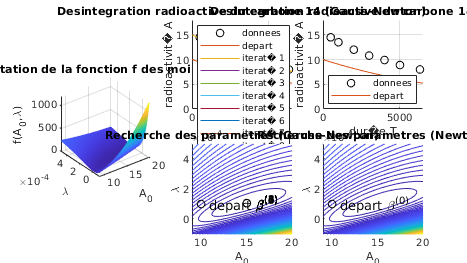


options = [sqrt(eps) 1.e-12 0];

for i = 1:nb_iterations_max
    txt_legend{i+2} = ['iterat� ' num2str(i)];
    options(3) = i;
    [beta, norm_grad_f_beta, f_beta, norm_delta, k, exitflag] = ...
        Algo_Gauss_Newton(@(beta) residu_C14(beta, Donnees), ...
        @(beta) J_residu_C14(beta, Donnees), ...
        beta0, options);
    disp([k beta(1) beta(2) norm_grad_f_beta f_beta norm_delta exitflag])
    % Visualisation
    A = beta(1)*exp(-beta(2)*T);
    subplot(2, 3, 2)
    plot(T,A)
    legend(txt_legend{1:i+2})
    %  eval(['print -depsc fig_GN_courbe' int2str(i) '_C14'])
    subplot(2, 3, 5)
    plot(beta(1),beta(2),'ok')
    text(beta(1),beta(2),['  \beta^{(' num2str(i) ')}'])
    
    pause(0.5)
end


% Affichage des itérés de beta et sauvegarde des graphique
disp('--------------------------------------------------------------------------------------------')

--------------------------------------------------------------------------------------------


## Newton

------- Initialisation de l'affichage

disp('Algorithme de Newton')

Algorithme de Newton


disp('--------------------')

--------------------


% Initialisation de l'affichage
[H, ~, ~] = Hess_f_C14(beta0, Donnees, ...
    @(beta) residu_C14(beta, Donnees), ...
    @(beta) J_residu_C14(beta, Donnees));
disp('Hessienne f(beta^{(0)})')

Hessienne f(beta^{(0)})


disp(H)

       4.0436       -96820
       -96820    3.631e+09




disp('--------------------------------------------------------------------------------------------')

--------------------------------------------------------------------------------------------


disp('     nb_iter         A0        lambda    ||f''(beta)||     f(beta)    ||delta||     exitflag ')

     nb_iter         A0        lambda    ||f'(beta)||     f(beta)    ||delta||     exitflag 


disp('--------------------------------------------------------------------------------------------')

--------------------------------------------------------------------------------------------



% Calcul et affichage des valeurs initiales
res_beta = residu_C14(beta0, Donnees);
f_beta = 0.5*(res_beta.')*res_beta;
J_res_beta = J_residu_C14(beta0, Donnees);
norm_grad_f_beta = norm((J_res_beta.')*res_beta);
disp([0 beta0(1) beta0(2) norm_grad_f_beta f_beta]);

            0           10       0.0001   4.6322e+05        48.07




options = [sqrt(eps) 1.e-12 0];

for i = 1:nb_iterations_max
    options(3) = i;
    % Algorithme de Newton
    [beta, norm_grad_f_beta, f_beta, norm_delta, k, exitflag] = ...
        Algo_Newton(@(beta) Hess_f_C14(beta, Donnees, ...
        @(beta) residu_C14(beta, Donnees), ...
        @(beta) J_residu_C14(beta, Donnees)), ...
        beta0, options);
    % Affichage des valeurs
    disp([k beta(1) beta(2) norm_grad_f_beta f_beta norm_delta exitflag])
    % Visualisation
    A = beta(1)*exp(-beta(2)*T);
    subplot(2, 3, 3)
    plot(T,A)
    legend(txt_legend{1:i+2})
    subplot(2, 3, 6)
    plot(beta(1),beta(2),'ok')
    text(beta(1),beta(2),['  \beta^{(' num2str(i) ')}'])
    
    pause(0.5)
end

  Columns 1 through 6

            1  -2.3183e+09  -2.3183e+09    9.374e+09    4.687e+09   2.3183e+09

  Column 7

            2

  Columns 1 through 6

            1  -2.3183e+09  -2.3183e+09    9.374e+09    4.687e+09   2.3183e+09

  Column 7

            2

  Columns 1 through 6

            1  -2.3183e+09  -2.3183e+09    9.374e+09    4.687e+09   2.3183e+09

  Column 7

            2

  Columns 1 through 6

            1  -2.3183e+09  -2.3183e+09    9.374e+09    4.687e+09   2.3183e+09

  Column 7

            2

  Columns 1 through 6

            1  -2.3183e+09  -2.3183e+09    9.374e+09    4.687e+09   2.3183e+09

  Column 7

            2

  Columns 1 through 6

            1  -2.3183e+09  -2.3183e+09    9.374e+09    4.687e+09   2.3183e+09

  Column 7

            2

  Columns 1 through 6

            1  -2.3183e+09  -2.3183e+09    9.374e+09    4.687e+09   2.3183e+09

  Column 7

            2

  Columns 1 through 6

            1  -2.3183e+09  -2.3183e+09    9.374e+09    4.687e+09  


% Affichage des iteres de beta et sauvegarde des courbes
disp('--------------------------------------------------------------------------------------------')

--------------------------------------------------------------------------------------------


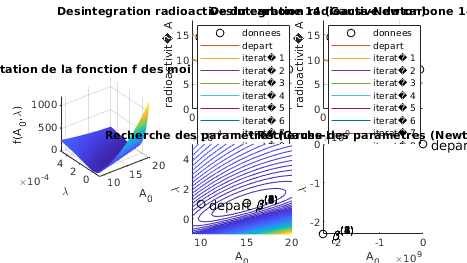

print('C14_figures','-dpng')

diary

## Fonctions a coder : residu, Jacobienne, Hessienne

%%------------------------------------------------------------------------%                                                                     %
% Fonction de calcul du residu de la fonction de desintegration           %
% radioactive du carbone 14                                               %
%-------------------------------------------------------------------------%


function res = residu_C14(beta, donnees)
%
% Paramètres en entrés
% --------------------
% beta : vecteur des paramètres
%         real(p)
% donnees : Données
%           real(n,2)
%
% Paramètres en sortie
% --------------------
% res    : vecteur des résidus
%          real(n)
%
% TO DO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

res = donnees(:,2) - beta(1)*exp(-beta(2)*donnees(:,1));

end

%-------------------------------------------------------------------------%                                                                        %
% Fonction de calcul de la Jacobienne du residu de la fonction de         %
% desintegration radioactive du carbone 14                                %
%-------------------------------------------------------------------------%

function J_res = J_residu_C14(beta, donnees)
%
% Paramètres en entrés
% --------------------
% beta : vecteur des paramètres
%         real(p)
% donnees : Données
%           real(n,2)
%
% Paramètres en sortie
% --------------------
% J_res    : Matrice jacobienne des résidus
%            real(n,p)
%
% TO DO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
J_res = [-exp(-beta(2)*donnees(:,1)) beta(1)*(donnees(:,1).*exp(-beta(2)*donnees(:,1)))];
    
end

%-------------------------------------------------------------------------%
% Fonction de calcul de la Hessienne des moindres carres de la fonction   %
% de desintegration radioactive du carbone 14                             %
% (residu et J_residu sont des fonctions en entree)                       %
%-------------------------------------------------------------------------%

function [H_f, res, J_res] = Hess_f_C14(beta, donnees, residu, J_residu)
%
% Paramètres en entrés
% --------------------
% beta     : vecteur des paramètres
%            real(p)
% donnees  : Données
%            real(n,2)
% residu   : fonction qui code les résidus
%            res_beta = residus(beta)
% J_residu : fonction qui code la matrice jacobienne
%            J_res_beta = J_residu(beta);
%
% Paramètres en sortie
% --------------------
% H_f      : Matrice hessienne
%            real(p,p)
% res      : vecteur des résidus
%            real(n)
% J_res    : Matrice jacobienne des résiduis
%            real(n,p)
%
% TO DO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
res = donnees(:,2) - beta(1)*exp(-beta(2)*donnees(:,1));
J_res = [-exp(-beta(2)*donnees(:,1)) beta(1)*(donnees(:,1).*exp(-beta(2)*donnees(:,1)))];
H_f = J_res'*J_res;









end